## Pablo Vega Gallego, Adrian Cristian Crisan, Filip Gedung Dorm, VC, FIB. 

# Sessió 6

El mateix que l'altre exercici però amb un binaritzat local.

No hem aconseguit un molt bon resultat.

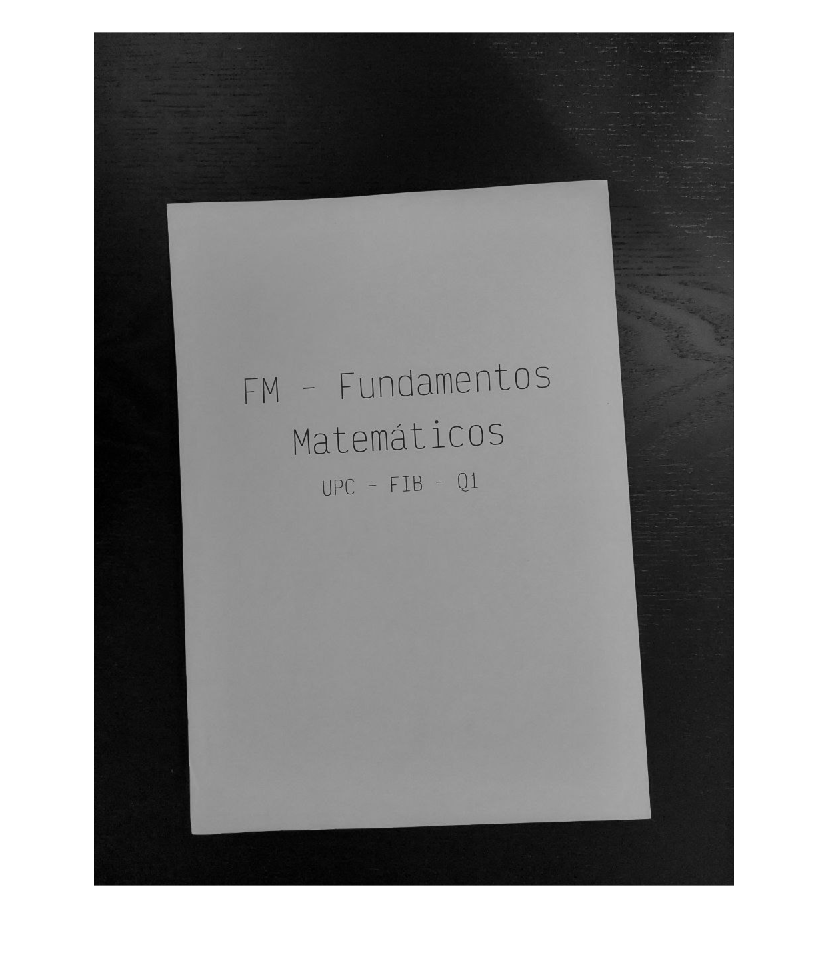

imagen_original = imread('foto1.jpeg');
imagen_grises = rgb2gray(imagen_original);

H = fspecial('gaussian');
imagen_grises = imfilter(imagen_grises, H);

imshow(imagen_grises);

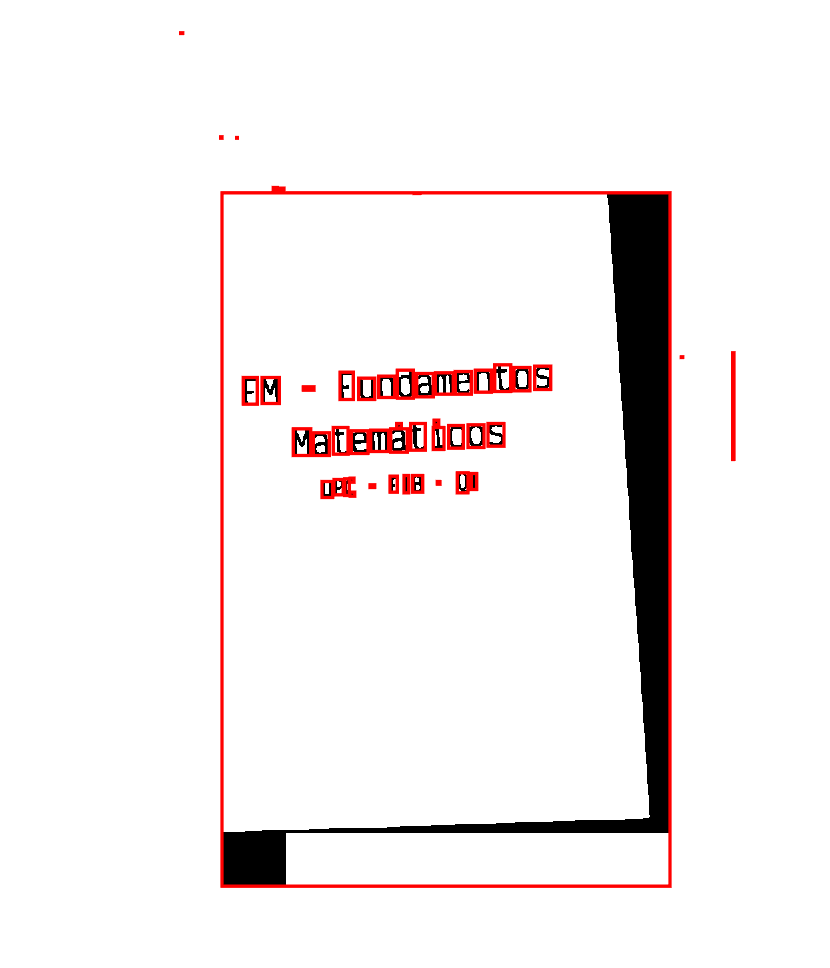

imagen_binarizada = colfilt(imagen_grises, [5 5], 'sliding', @myfunction);
imshow(imagen_binarizada, []);
labeledImage = bwconncomp(~imagen_binarizada);
			measurements = regionprops(labeledImage,'BoundingBox');
for k = 1 : length(measurements)
thisBB = measurements(k).BoundingBox;
rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],...
'EdgeColor','r','LineWidth',2 )
end

function theta = rotacion(imagen)
    [y, x] = find(imagen);
    
    nx = x - mean(x);
    ny = y - mean(y);
    
    nx = nx';
    ny = ny';
    
    c = cov(nx, ny);
    [evectors, evalues] = eig(c);
    
    [~, ind] = max(diag(evalues));
    
    theta = -pi/2-atan2(evectors(ind, 2), evectors(ind, 1));
end

function [y] = myfunction(c)
    [f col] = size(c);
    media = sum(c)/f;
    y = c(fix(f/2)+1)<media+20;
end